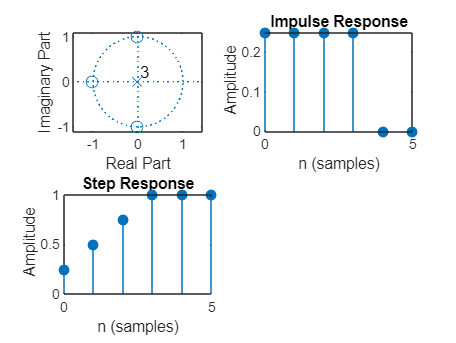

clc
clear
close all
fs = 200;
b = [0.25 0.25 0.25 0.25];
a = 1;
figure('Color','w')
subplot 221
zplane(b, a)
subplot 222
impz(b, a, 6)
subplot 223
stepz(b, a, 6)

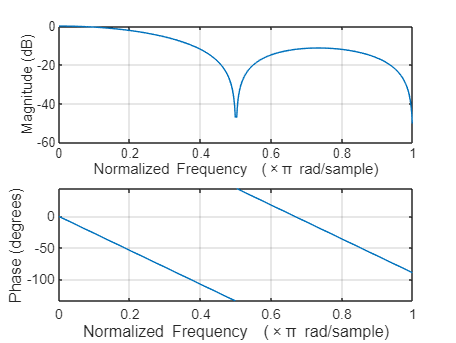

figure('Color','w')
freqz(b,a)

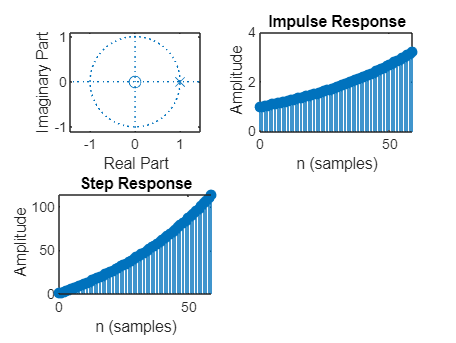

%Compound interest
clc
clear
close all
fs = 200;
b = 1;
a = [1 -1.02];
figure('Color','w')
subplot 221
zplane(b, a)
subplot 222
impz(b, a, 60)
subplot 223
stepz(b, a, 60)

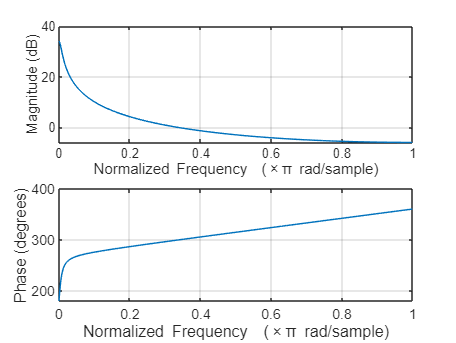

figure('Color','w')
freqz(b,a)

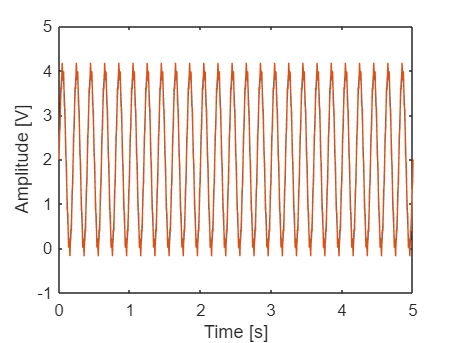

clc
clear
close all
fs = 200;
t = 0: 1/fs : 5;
desired_signal = 2 * sin(2*pi*5*t) + 2;
figure1 = figure('Color','w');
plot(t,desired_signal,'DisplayName', 'Chilakill')
ylabel ('Amplitude [V]');
xlabel ('Time [s]')
noise = 0.2 * sin(2*pi*50*t);
total = desired_signal + noise;
hold on
plot(t, total, 'DisplayName', 'Total')

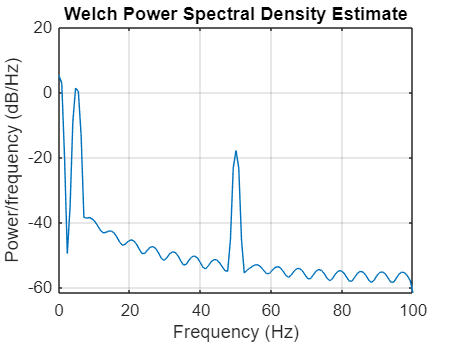

figure
pwelch(total, [], [], [], fs)

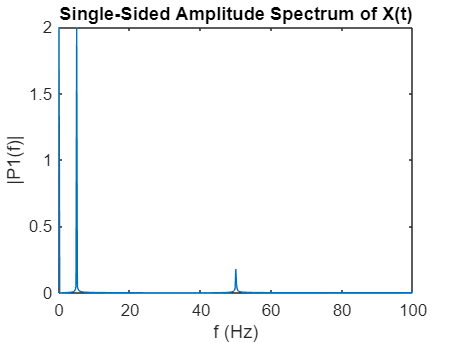

plotFFT(total, fs)

fc = 8;
[b, a] = butter(1, fc/(fs/2));
figure('Color','w')
subplot 221
zplane(b, a)
subplot 222
impz(b, a, 60)
subplot 223
stepz(b, a, 60)
figure('Color','w')
freqz(b,a,fs)
filtered = filter(b, a, total);
figure(figure1)
plot(t, filtered, 'DisplayName', 'Filtered')
figure
pwelch(filtered, [], [], [], fs)

%CANCION
clear
close all
[song, fs] = audioread('song.wav')

song =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

sound(0.5*song, fs);

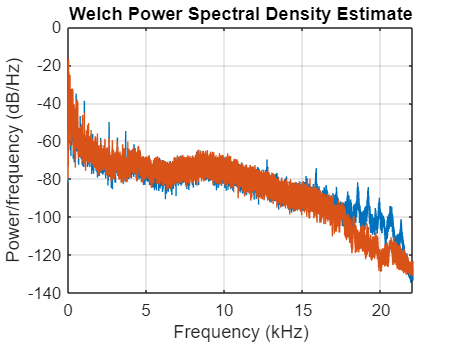

figure
pwelch(song, [], [], [], fs)

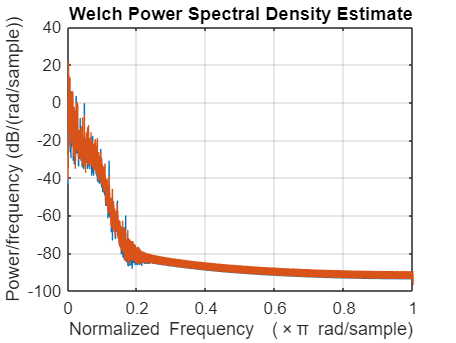

fc = 2000;  
[b, a] = butter(8, fc/(fs/2));
song_filt = filter(b,a,song);
sound(song_filt);
pwelch(song_filt)

%Violin
[violin, fs] = audioread('violin.wav')
figure
stft(violin, fs)